% First make an instance of the project class
problem = projectClass('DSPC custom layers');


% Make this a custom layers model
problem.setModelType('custom layers');


% Define the parameters:
Parameters = {
    %       Name                min       val      max       fit? 
    {'Area per molecule',        45,      52,      65,       true};
    {'Head Hydration',           0,       0.2,     0.5,      true};
    {'Head Roughness',           3,       5,       7,        true};
    {'Tail Roughness',           3,       5,       7,        true};
    };


% Add the parameters and Layers to the project:
problem.addParamGroup(Parameters);

% Increase the constr range for Substrate Roughness (param 1)
problem.setParamConstr(1,2,13);

% Add the custom layers file
problem.addCustomFile({'DSPC Model','custom_DSPC_monolayer.m','matlab','pwd'});

% Need two backgrounds - one for D2O and for H2O
% Change the name of the first and add a new one for the second
% Also need a new backsPar
problem.setBacksParName(1,'Backs value ACMW');
problem.setBacksParValue(1,5.5e-6);
problem.addBacksPar('Backs Value D2O',1e-8,2.8e-6,1e-5);

problem.addBackground('Background D2O','constant','Backs Value D2O');
problem.setBackgroundValue(1,'name','Background ACMW');
problem.setBackgroundValue(1,3,'Backs Value ACMW');


% Also need an additional bulk out
problem.addBulkOut({'SLD ACMW' -1e-6,0.0,1e-6,true});

% Add the data files
d13ACM = dlmread('d13acmw20.dat');
d70d2O = dlmread('d70d2o20.dat');
problem.addData('H-tail / D-head / ACMW', d13ACM);
problem.addData('D-tail / H-head / D2O', d70d2O);

% Add the contrasts
problem.addContrast('name','D-tail/H-Head/D2O',...
    'background','Background D2O',...
    'resolution','Resolution 1',...
    'scalefactor', 'Scalefactor 1',...
    'nbs', 'SLD D2O',...
    'nba', 'SLD air',...
    'data', 'D-tail / H-head / D2O');
problem.setContrastModel(1,'DSPC Model');

problem.addContrast('name','H-tail/D-Head/ACMW',...
    'background','Background ACMW',...
    'resolution','Resolution 1',...
    'scalefactor', 'Scalefactor 1',...
    'nbs', 'SLD ACMW',...
    'nba', 'SLD air',...
    'data', 'H-tail / D-head / ACMW');
problem.setContrastModel(2,'DSPC Model');


% Set the fitting fitting flag on some parameters we need to fit
problem.setBacksPar(1,'fit',true);
problem.setBacksPar(2,'fit',true);
problem.setScalefactor(1,'fit',true);
problem.setBulkOut(1,'fit',true);

% Display problem
problem

problem =          ModelType: 'custom layers'
    experimentName: 'DSPC custom layers'
          Geometry: 'air/substrate'

    Parameters: ---------------------------------------------------------------------------------------------- 

    p            Name             Min    Value    Max    Fit? 
    _    _____________________    ___    _____    ___    _____

    1    "Substrate Roughness"     2        3      13    true 
    2    "Area per molecule"      45       52      65    true 
    3    "Head Hydration"          0      0.2     0.5    true 
    4    "Head Roughness"          3        5       7    true 
    5    "Tail Roughness"          3        5       7    true 

    Bulk In: -------------------------------------------------------------------------------------------------- 

  


% Make the controls class...
controls = controlsDef();
controls.parallel = 'points';

disp(controls)

  controlsDef with properties:

            parallel: 'points'
           procedure: 'calculate'
    calcSldDuringFit: 'no'






[problem,results] = RAT(problem,controls);

Starting RAT ________________________________________________________________________________________________ 

Elapsed time is 0.006454 seconds.

Finished RAT ______________________________________________________________________________________________ 




disp(results)

          reflectivity: {2×1 cell}
            Simulation: {2×1 cell}
          shifted_data: {2×1 cell}
             layerSlds: {2×1 cell}
           sldProfiles: {2×1 cell}
             allLayers: {2×1 cell}
    calculationResults: [1×1 struct]
        contrastParams: [1×1 struct]
              fitNames: {10×1 cell}



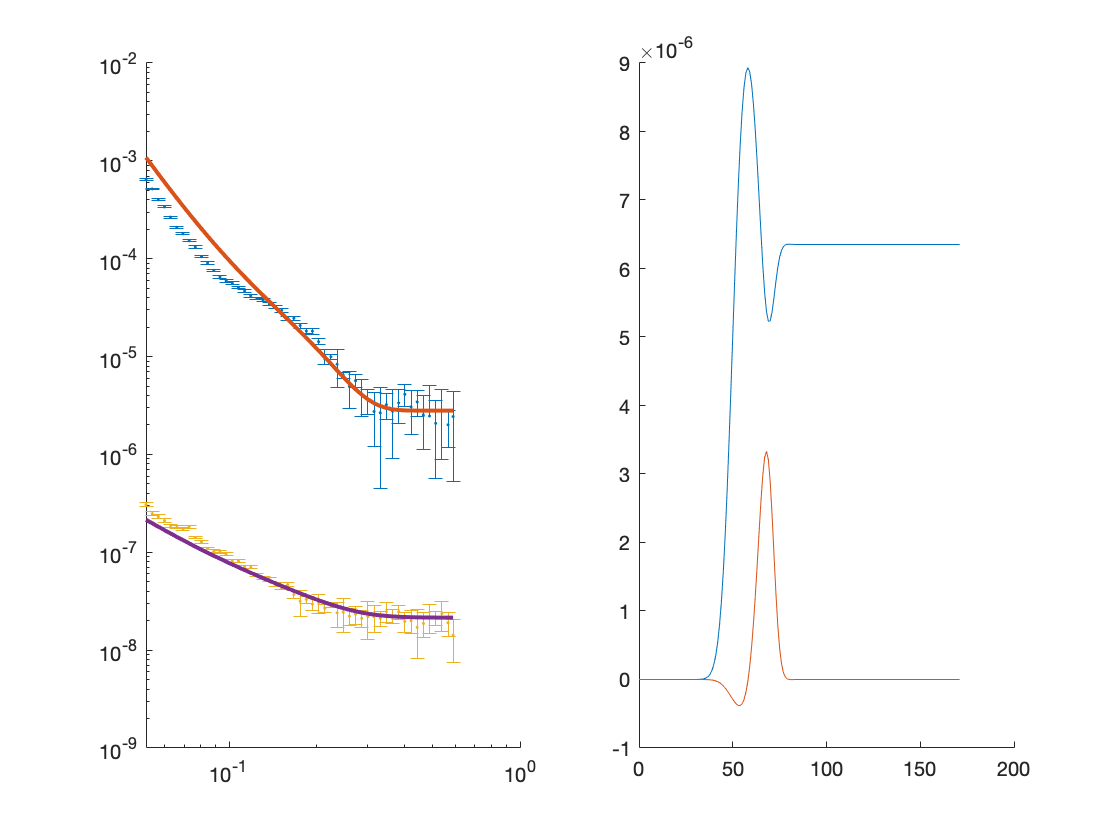

figure(1); clf
plotRefSLD(problem,results)

%controls.procedure = 'simplex'

controls =   controlsDef with properties:

            parallel: 'points'
           procedure: 'simplex'
    calcSldDuringFit: 'no'
             display: 'iter'
                tolX: 1.0000e-06
              tolFun: 1.0000e-06
         maxFunEvals: 10000
             maxIter: 1000


%[out,results] = RAT(problem,controls)

Starting RAT ________________________________________________________________________________________________ 

Running Sinplex 
 
 Iteration   Func-count     min f(x)         Procedure
     0            1          396.961         
     1           11           394.41         initial simplex
     2           13          350.547         expand
     3           14          350.547         reflect
     4           15          350.547         reflect
     5           16          350.547         reflect
     6           17          350.547         reflect
     7           18          350.547         reflect
     8           19          350.547         reflect
     9           20          350.547         reflect
    10           21          350.547         reflect
    11           22          350.547         reflect
    12           24          321.941         expand
    13           25          321.941         reflect
    14           26          321.941         reflect
    15           27 

out =          ModelType: 'custom layers'
    experimentName: 'DSPC custom layers'
          Geometry: 'air/substrate'

    Parameters: ---------------------------------------------------------------------------------------------- 

    p            Name             Min      Value      Max    Fit? 
    _    _____________________    ___    _________    ___    _____

    1    "Substrate Roughness"     2        2.0191     13    true 
    2    "Area per molecule"      45        45.862     65    true 
    3    "Head Hydration"          0     0.0058487    0.5    true 
    4    "Head Roughness"          3        4.9932      7    true 
    5    "Tail Roughness"          3        4.9837      7    true 

    Bulk In: -------------------------------------------------------------------------------

results = struct with fields:
          reflectivity: {2×1 cell}
            Simulation: {2×1 cell}
          shifted_data: {2×1 cell}
             layerSlds: {2×1 cell}
           sldProfiles: {2×1 cell}
             allLayers: {2×1 cell}
    calculationResults: [1×1 struct]
        contrastParams: [1×1 struct]
              fitNames: {10×1 cell}


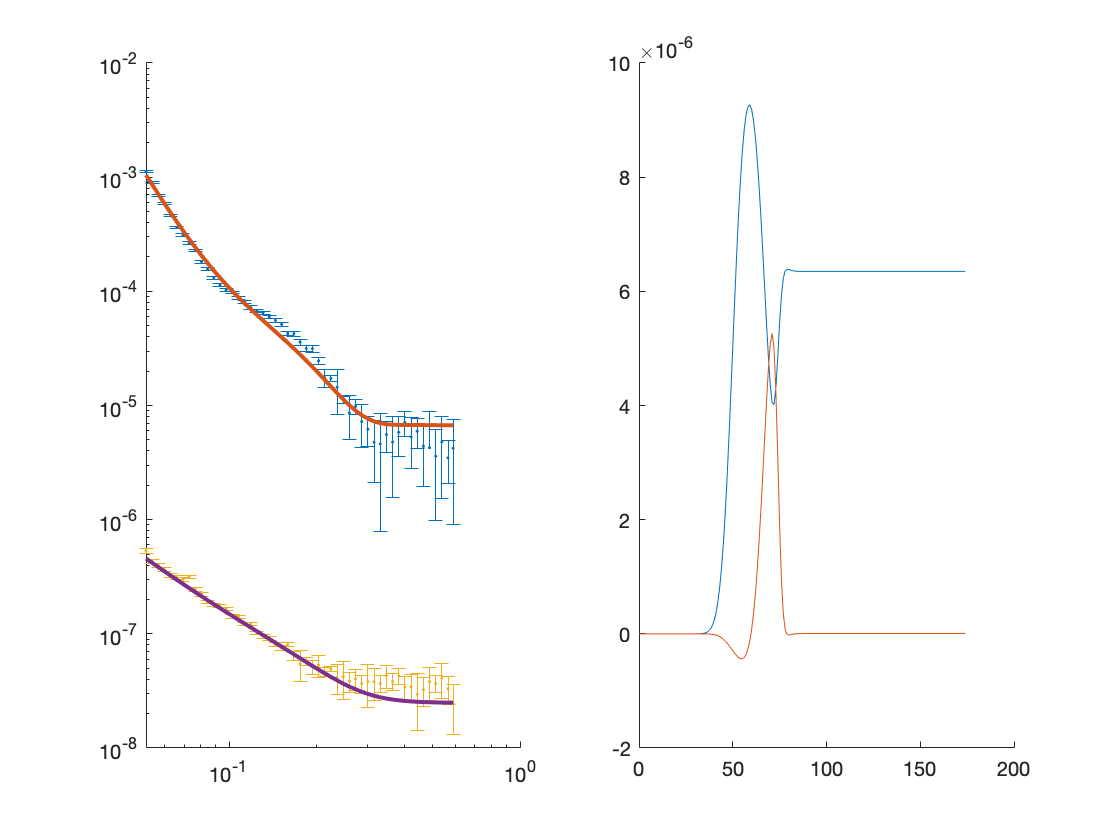

% figure; clf
% plotRefSLD(out,results)

save('twoContrastExample.mat','problem');

Custom model file: